MATLAB 画环形比例图

https://blog.csdn.net/L_J_Kin/article/details/123901573

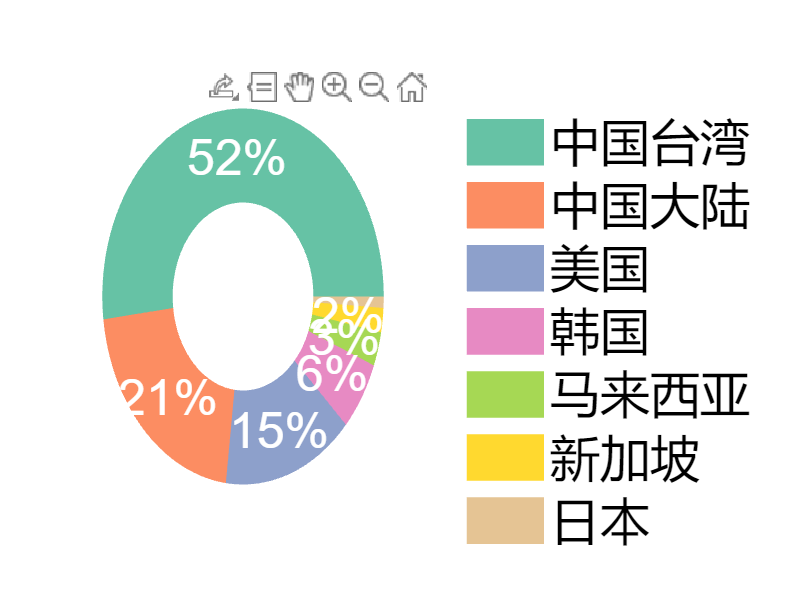

%%
clc;
% clear;

%% 
% 图例和加载的数据
% 数据（figdata）需要用户自行输入
% 图例（figlegs）的文本可以省略，以{''; ''; ...}的格式，长度和数据（figdata）保持一致
% 用户仅需要更改 figdata 和 figlegs 即可
% figdata = [207; 82; 25; 19; 13; 11; 8; 3];
% figlegs = {'Type I'; 'Type II'; 'Type III'; 'Type IV'; 
%     'Type V'; 'Type VI'; 'Type VII'; 'Type VIII'};
% figdata = [0.33; 0.19; 0.12; 0.11; 0.11; 0.04; 0.04; 0.06];
figdata = [0.52; 0.21; 0.15; 0.06; 0.03; 0.02; 0.01];
figlegs = {'PECVD'; '溅射PVD'; '管式CVD'; 'ALD'; 
    '非管式LPCVD'; '电镀ECD'; 'MOCVD'; '其它'};
figlegs = {'中国台湾'; '中国大陆'; '美国'; '韩国'; 
    '马来西亚'; '新加坡'; '日本'};


figdata = [0.2711; 0.1408; 0.1071; 0.0651; 0.0611;  0.0385;0.0348; 0.0268;...
    0.0175;0.0171;0.2201];
%%
% 图像主要参数设置
% 图像的长和宽
figwidth = 800;
figheight = 600;

% 每个类别的颜色
clrs = [
    0.3010 0.7450 0.9330; 
    0 0.4470 0.7410;
    0.4940 0.184 0.5560;
    1 0 0;
    0.8500 0.3250 0.0980;
    0.4660 0.6740 0.1880;
    0.6350 0.0780 0.1840;
    0 0 1
    ];
[clrs,~,~,~] = brewermap(7,'Set2');

%%
% 输入数据处理
% 计算每个类别的百分比
perdata = figdata / sum(figdata(:));

% 设置小梯形的个数，最好是360的整数倍
pienum = 720;

% 使用patch函数填充小梯形，即pienum等份
% 计算每个类别占用小梯形的份数
% 以及每类的起始位置
perdata = figdata / sum(figdata(:)); 
perclass = perdata * pienum;

endpts = zeros(size(perclass));
for i = 1 : length(endpts)
    endpts(i) = sum(perclass(1 : i));
end
endpts = floor(endpts + 0.5);
beginpts = ones(size(endpts));
beginpts(2 : end) = endpts(1 : end - 1) + 1;

% 每个类型所显示的比例也是整数，因此需要四舍五入
percentdata = floor(perdata  * 100 + 0.5);

%%
% 图像展示
figure(1);
gc = get(gca);
set(gcf, 'position', [0, 50, figwidth, figheight]);

% 设置外环和内环，需要比单元格的数量多1
% 首边和末边重合，此处，0就是2 PI（360度）
phi = linspace(0, 2 * pi, pienum + 1);

sizeInner = 0.75;
sizeOuter = 1.5;
innerRim = [cos(phi)', sin(phi)'] * sizeInner;
outerRim = [cos(phi)', sin(phi)'] * sizeOuter;

% patch函数填充，填充的对象为梯形，共计pienum个小梯形
% xRing和YRing分别记录了每个小梯形的x坐标和y坐标
xRing = [outerRim(:, 1), innerRim(:, 1), innerRim([2 : end, 1], 1), outerRim([2 : end, 1], 1)]';
yRing = [outerRim(:, 2), innerRim(:, 2), innerRim([2 : end, 1], 2), outerRim([2 : end, 1], 2)]';

% 为了方便绘制图例，记录每个patch
s_ps = [];
% 为了防止压盖文字，记录文字的位置和文字内容
X_Y_percents = [];

for i = 1 : length(figdata)
    % 读取每个类型的起始位置
    curlt = beginpts(i) : endpts(i);
    % 对应梯形的位置
    curXRing = xRing(:, curlt);
    curYRing = yRing(:, curlt);
    s_p = patch(curXRing, curYRing, clrs(i, :), 'EdgeColor', 'none');
    
    % 获取每个类型的中心位置，填充文字
    curX = mean(curXRing(:));
    curY = mean(curYRing(:));
    
    % 将文字中心调整到内环和外环的中心环处
    tms = 1.0 / sqrt(curX ^ 2 + curY ^ 2) * (sizeInner + sizeOuter) / 2;
    curX = mean(curXRing(:)) * tms;
    curY = mean(curYRing(:)) * tms;
        
    X_Y_percents = [X_Y_percents; [curX, curY, percentdata(i)]];
    
    s_ps = [s_ps; s_p];
    hold on;
end

% 防止图形压盖文字
for i = 1 : length(figdata)
    if X_Y_percents(i, 3) >= 2
        text(X_Y_percents(i, 1), X_Y_percents(i, 2), ...
            strcat(num2str(X_Y_percents(i, 3)), '%'), ...
            'FontSize', 20, 'FontName', 'Arial', 'Color', 'w', ...
            'HorizontalAlignment', 'center');
    end
end

% 加载汇总文字（根据需求进行修改）
% text(0, 0, ['频次总计：', sprintf('\n'), num2str(sum(figdata(:))), '次'], ...
%     'FontSize', 24, 'FontName', '宋体', 'Color', 'k', ...
%     'HorizontalAlignment', 'center');

% 加载图例
h1 = legend(s_ps, figlegs, 'Location', 'southeastoutside');
set(h1, 'FontName', '微软雅黑', 'FontSize', 20, 'FontWeight', 'normal');
hold on;
legend('boxoff');

% 其他设置，防止圆环变形，并去掉轴，设置底色为白色
axis square
axis off
set(gcf, 'color', 'w');

% 加载图形编号，此处在左上角加载“(a)”
rr = axis; 
% text(rr(1), rr(4), '(a)', 'FontSize', 28, 'FontName', 'Arial', ...
%     'Color', 'k', 'HorizontalAlignment', 'center');

% 裁剪图像的外边缘的空白部分
set(gca, 'looseInset', [0.03, 0.03, 0.03, 0.03]);